% Note that x(k) = (k-1) * dt
close all;
clear;
clc;

T = 100;
dt = 0.1;
steps = T / dt + 1 

steps = 1001

time = linspace(0,T,steps);
n = 3;
s = 100;

sigmaY = eye(3) .*1e-5;
sigmaX = eye(3) .*1e-9;

### LEVEL I: ThreeTank

load Parameter_Modell_1.mat;

parameter.c13 = c13;
parameter.c32 = c32;
parameter.cA2 = c13;
parameter.u = Q_z1_max;
parameter.A = 0.0154;
parameter.g = 9.81;

%Save to json file
jsonParameter = jsonencode(parameter);
fid = fopen('ParameterModell1.json', 'w');
fprintf(fid, '%s', jsonParameter);
fclose(fid);

parameter.dt = dt;
parameter.sigmaX = sigmaX;
parameter.sigmaY = sigmaY;
parameter.c = [1,0,0;0,1,0;0,0,1];

#### Noise free simulation for tests


parameter.sigmaX = zeros(n,n);
parameter.sigmaY = zeros(n,n);

x = zeros(steps,n);
x(1,:) = x(1,:) + randn(1,n) * parameter.sigmaX; 
y = x ;
y(1,:) = y(1,:) + randn(1,n) * parameter.sigmaY; 

for k = 2 : steps 
    [x(k,:),y(k,:)] = solveThreeTank(x(k-1,:),parameter);
end

%plot(time,x(:,1),time,x(:,2),time,x(:,3))

#### create some data

%Reduce length and save to csv file
d = 10;
stepsReduced = floor(steps / d);
xReduced = zeros(stepsReduced,n);
for i = 0 : (steps / d)
    xReduced(i+1,:) = x(i*d + 1,:);
    timeReduced(i+1) = time(i*d + 1);
end

Header = ["t","x1","x2","x3"];
Table = table(timeReduced.',xReduced(:,1),xReduced(:,2),xReduced(:,3),'VariableNames',Header);


%writetable(Table,'threeTankSimNoiseFree.csv','Delimiter',';') ;

#### Noise added simulation for tests

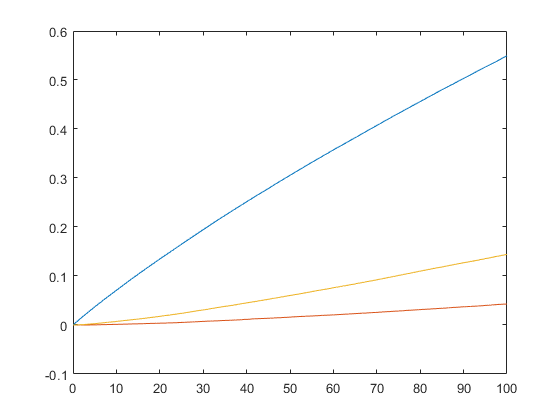


parameter.sigmaX = sigmaX;
parameter.sigmaY = sigmaY;

x = zeros(steps,n);
x(1,:) = x(1,:) + randn(1,n) * parameter.sigmaX; 
y = x ;
y(1,:) = y(1,:) + randn(1,n) * parameter.sigmaY; 

for k = 2 : steps 
    [x(k,:),y(k,:)] = solveThreeTank(x(k-1,:),parameter);
end

plot(time,x(:,1),time,x(:,2),time,x(:,3));

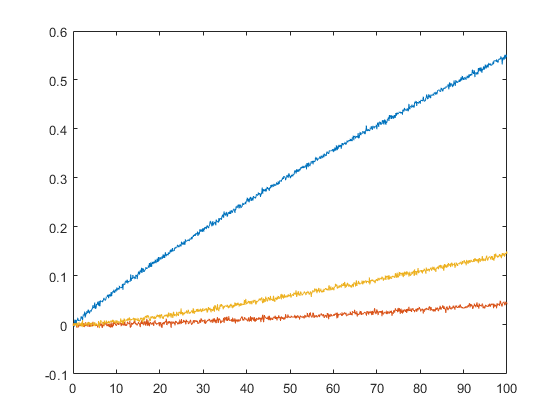

plot(time,y(:,1),time,y(:,2),time,y(:,3))

#### create some data

%Reduce length and save to csv file
d = 10;
stepsReduced = floor(steps / d);
xReduced = zeros(stepsReduced,n);
yReduced = zeros(stepsReduced,n);
dxReduced = zeros(stepsReduced,n);
timeReduced = zeros(stepsReduced,1);

for i = 0 : ((steps / d))
    xReduced(i+1,:) = x(i*d + 1,:);
    yReduced(i+1,:) = y(i*d + 1,:);
    %dxReduced(i+1,:) = x(i*d + 2,:) - x(i*d + 1,:);
    timeReduced(i+1,1) = time(i*d + 1);
end

for i = 0 : ((steps / d) - 1)
    dxReduced(i+1,:) = xReduced(i + 2,:) - xReduced(i + 1,:);
end

reducedLength = floor( (steps /d)+1)

reducedLength = 101

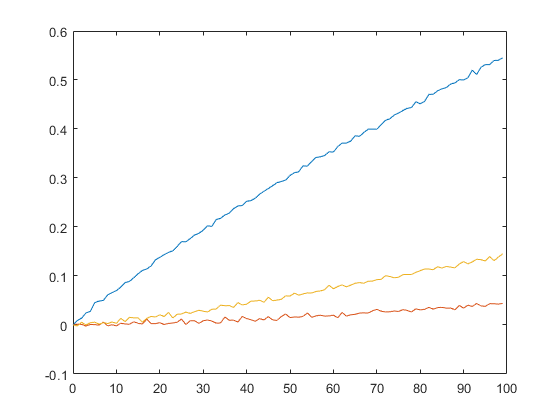


xReduced(reducedLength,:) = [];
yReduced(reducedLength,:) = [];
timeReduced(reducedLength,:) = [];


Header = ["t","x1","x2","x3","dx1","dx2","dx3","y1","y2","y3"];
Table = table(timeReduced(:,1),xReduced(:,1),xReduced(:,2),xReduced(:,3),dxReduced(:,1),dxReduced(:,2),dxReduced(:,3),yReduced(:,1),yReduced(:,2),yReduced(:,3),'VariableNames',Header);

plot(timeReduced,yReduced(:,1),timeReduced,yReduced(:,2),timeReduced,yReduced(:,3))

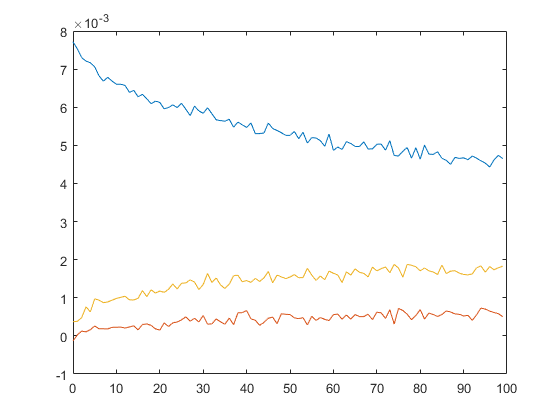

plot(timeReduced,dxReduced(:,1),timeReduced,dxReduced(:,2),timeReduced,dxReduced(:,3))


writetable(Table,'threeTankSim_dt1.csv','Delimiter',';') ;
save('threeTankSim_dt1.mat',"timeReduced","xReduced","dxReduced","yReduced");

### LEVEL II: Particle-Filter

%

### LEVEL III: Gaussian Process

%